**08**

clear
format short
digits(3)
U=100; % В
R=20; % Ом
X_L=5; % Ом
X_C=10; % Ом
Ud=U;

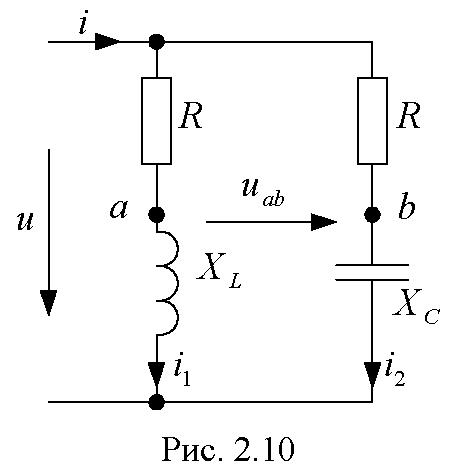

Комплексные сопротивления

Z1=R, Z2=1j*X_L, Z3=R, Z4=-1j*X_C

Z1 = 20

Z2 = 0.0000 + 5.0000i

Z3 = 20

Z4 = 0.0000 - 10.0000i

Z12=Z1+Z2, Z34=Z3+Z4

Z12 = 20.0000 + 5.0000i

Z34 = 20.0000 - 10.0000i

Z=Z12*Z34/(Z12+Z34)

Z = 11.3846 - 1.0769i

Ток на входе цепи

Id=Ud/Z, Ip=vpa([abs(Id),angle(Id)*180/pi])

Id = 8.7059 + 0.8235i

$$Ip = \left(\begin{array}{cc} 8.74 & 5.4 \end{array}\right)$$

Токи в ветвях 1 и 2

Id1=Ud/Z12, Ip1=vpa([abs(Id1),angle(Id1)*180/pi])

Id1 = 4.7059 - 1.1765i

$$Ip1 = \left(\begin{array}{cc} 4.85 & -14.0 \end{array}\right)$$

Id2=Ud/Z34, Ip2=vpa([abs(Id2),angle(Id2)*180/pi])

Id2 = 4.0000 + 2.0000i

$$Ip2 = \left(\begin{array}{cc} 4.47 & 26.6 \end{array}\right)$$

Действующие значения токов ветвей

I=Ip(1),I1=Ip1(1), I2=Ip2(1)

$$I = 8.74$$

$$I1 = 4.85$$

$$I2 = 4.47$$

Напряжения на элементах и между точками a и b

Ud_R1=Id1*Z1, Up_R1=vpa([abs(Ud_R1),angle(Ud_R1)*180/pi])

Ud_R1 = 94.1176 - 23.5294i

$$Up\_R1 = \left(\begin{array}{cc} 97.0 & -14.0 \end{array}\right)$$

Ud_L=Id1*Z2, Up_L=vpa([abs(Ud_L),angle(Ud_L)*180/pi])

Ud_L = 5.8824 + 23.5294i

$$Up\_L = \left(\begin{array}{cc} 24.3 & 76.0 \end{array}\right)$$

Ud_R2=Id2*Z3, Up_R2=vpa([abs(Ud_R2),angle(Ud_R2)*180/pi])

Ud_R2 = 80.0000 + 40.0000i

$$Up\_R2 = \left(\begin{array}{cc} 89.4 & 26.6 \end{array}\right)$$

Ud_C=Id2*Z4, Up_C=vpa([abs(Ud_C),angle(Ud_C)*180/pi])

Ud_C = 20.0000 - 40.0000i

$$Up\_C = \left(\begin{array}{cc} 44.7 & -63.4 \end{array}\right)$$

Ud_ab=Ud_R2-Ud_R1, Up_ab=vpa([abs(Ud_ab),angle(Ud_ab)*180/pi])

Ud_ab = -14.1176 + 63.5294i

$$Up\_ab = \left(\begin{array}{cc} 65.1 & 103.0 \end{array}\right)$$

S=Ud*Id'

S = 8.7059e+02 - 8.2353e+01i

Sd_Z=Id1^2*Z1+Id1^2*Z2+Id2^2*Z3+Id2^2*Z4

Sd_Z = 8.7059e+02 + 8.2353e+01i

x=[0,real(Id)]

x =          0    8.7059


y=[0,imag(Id)]

y =          0    0.8235


plot(x,y,'b')
xlim([-10,10])
ylim([-10,10])
hold on
x=[0,real(Id1)]

x =          0    4.7059


y=[0,imag(Id1)]

y =          0   -1.1765


plot(x,y,'b')
x=[0,real(Id2)]

x =      0     4


y=[0,imag(Id2)]

y =      0     2


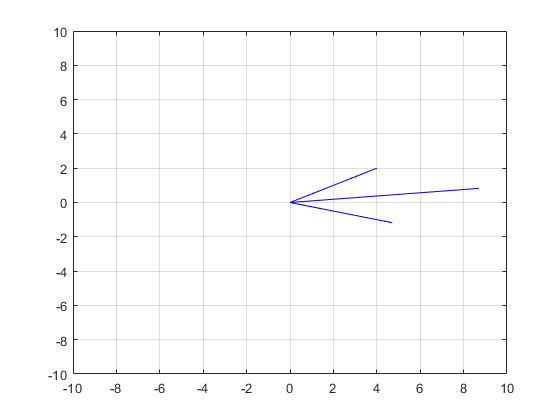

plot(x,y,'b')
grid
hold off

x=[0,real(Ud)]

x =      0   100


y=[0,imag(Ud)]

y =      0     0


plot(x,y,'r')
xlim([-150,150])
ylim([-150,150])
hold on
x=[0,real(Ud_R1)]

x =          0   94.1176


y=[0,imag(Ud_R1)]

y =          0  -23.5294


plot(x,y,'g')
x=[0,real(Ud_R2)]

x =      0    80


y=[0,imag(Ud_R2)]

y =      0    40


plot(x,y,'g')
x=[0,real(Ud_L)]

x =          0    5.8824


y=[0,imag(Ud_L)]

y =          0   23.5294


plot(x,y,'b')
x=[0,real(Ud_C)]

x =      0    20


y=[0,imag(Ud_C)]

y =      0   -40


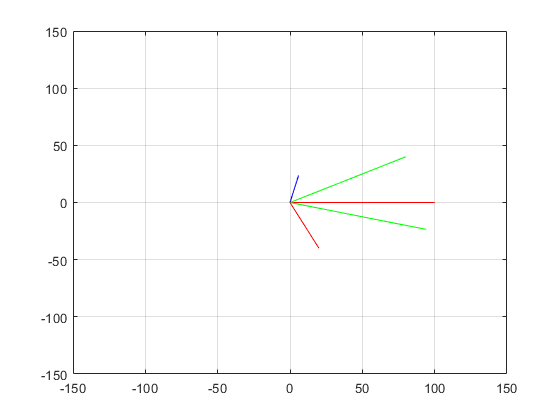

plot(x,y,'r')
grid
hold off

Ud_R1+Ud_L

ans = 100

Ud_R2+Ud_C

ans = 100

**09**

U=100;
R1=10;
R2=10;
R3=10;
X_L=20;
X_C=30;
Ud=U;


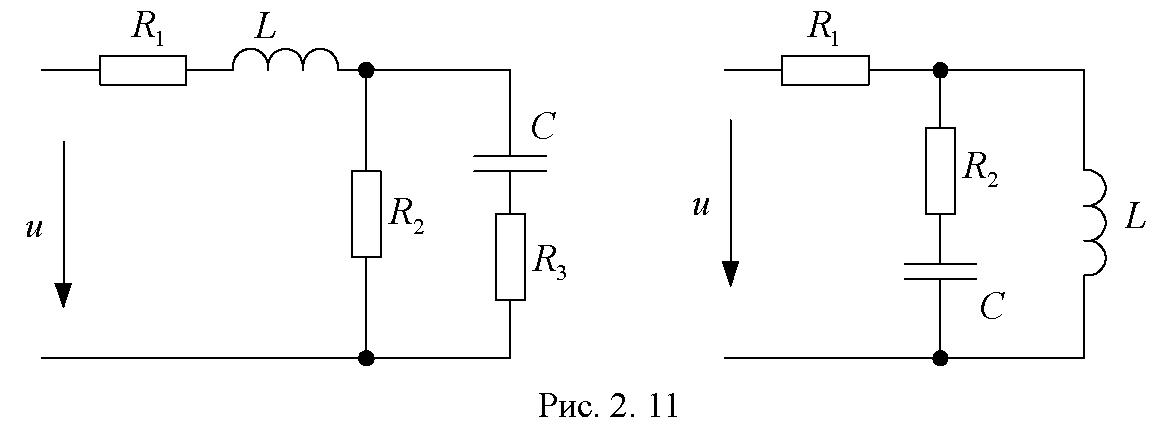

Z1=R1, Z2=1j*X_L, Z3=R2, Z4=-1j*X_C, Z5=R3

Z1 = 10

Z2 = 0.0000 + 20.0000i

Z3 = 10

Z4 = 0.0000 - 30.0000i

Z5 = 10

Z12=Z1+Z2

Z12 = 10.0000 + 20.0000i

Z45=Z4+Z5

Z45 = 10.0000 - 30.0000i

Z345=Z3*Z45/(Z3+Z45)

Z345 = 8.4615 - 2.3077i

Z=Z12+Z345

Z = 18.4615 + 17.6923i

Id=Ud/Z

Id = 2.8235 - 2.7059i

Ud1=Id*Z1

Ud1 = 28.2353 - 27.0588i

Ud2=Id*Z2

Ud2 = 54.1176 + 56.4706i

Ud345=Id*Z345

Ud345 = 17.6471 - 29.4118i

Id1=Ud345/Z3

Id1 = 1.7647 - 2.9412i

Id2=Ud345/Z45

Id2 = 1.0588 + 0.2353i

Ud3=Ud345

Ud3 = 17.6471 - 29.4118i

Ud4=Id2*Z4

Ud4 = 7.0588 - 31.7647i

Ud5=Id2*Z5

Ud5 = 10.5882 + 2.3529i

x=[0,real(Id)]

x =          0    2.8235


y=[0,imag(Id)]

y =          0   -2.7059


plot(x,y,'b')
xlim([-10,10])
ylim([-10,10])
hold on
x=[0,real(Id1)]

x =          0    1.7647


y=[0,imag(Id1)]

y =          0   -2.9412


plot(x,y,'g')
x=[0,real(Id2)]

x =          0    1.0588


y=[0,imag(Id2)]

y =          0    0.2353


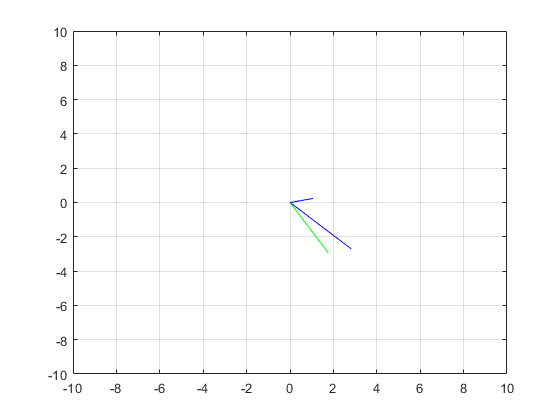

plot(x,y,'b')
grid
hold off

x=[0,real(Ud)]

x =      0   100


y=[0,imag(Ud)]

y =      0     0


plot(x,y,'r')
xlim([-150,150])
ylim([-150,150])
hold on
x=[0,real(Ud1)]

x =          0   28.2353


y=[0,imag(Ud1)]

y =          0  -27.0588


plot(x,y,'b')
x=[0,real(Ud2)]

x =          0   54.1176


y=[0,imag(Ud2)]

y =          0   56.4706


plot(x,y,'m')
x=[0,real(Ud3)]

x =          0   17.6471


y=[0,imag(Ud3)]

y =          0  -29.4118


plot(x,y,'g')
x=[0,real(Ud4)]

x =          0    7.0588


y=[0,imag(Ud4)]

y =          0  -31.7647


plot(x,y,'c')
x=[0,real(Ud5)]

x =          0   10.5882


y=[0,imag(Ud5)]

y =          0    2.3529


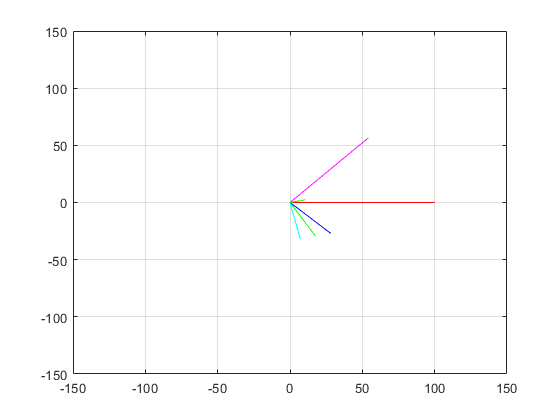

plot(x,y,'g')
grid
hold off